# Q3

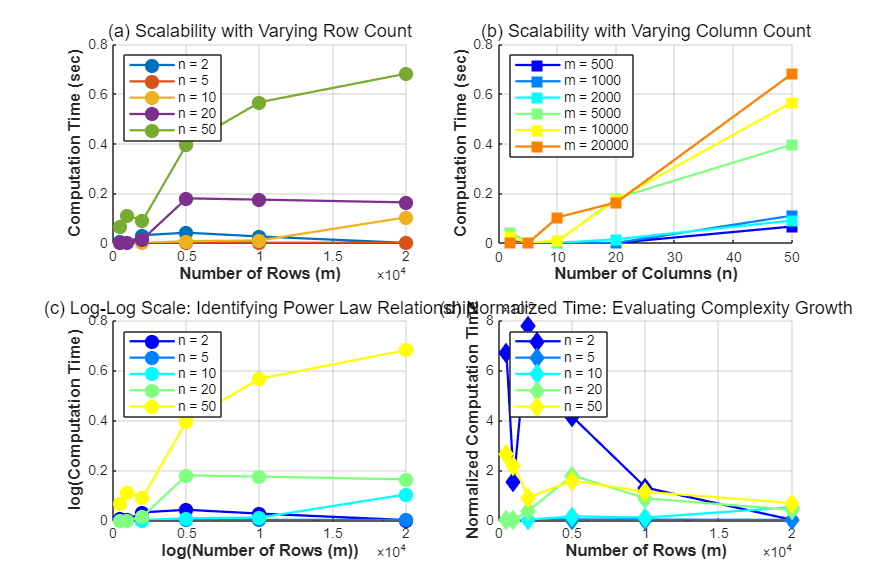

%% Data Preprocessing
clc; clear;
opts = detectImportOptions('scaling_results.csv');  % Detect import options for CSV file
opts.VariableNamingRule = 'preserve';  % Preserve original variable names
data = readtable('scaling_results.csv', opts);  % Read CSV file into a table

% Sort data based on 'm' values in ascending order
[~, idx] = sort(data.m);
data = data(idx, :);

%% Plot Scalability Charts
figure('Position', [100 100 1200 800], 'Color','w')  % Set figure size and background color

% ========== Subplot 1: Effect of m while keeping n fixed ==========
subplot(2,2,1)  % Create the first subplot
hold on; grid on;
n_values = unique(data.n);  % Get unique values of n
colors = lines(length(n_values));  % Generate distinct colors for different n values

for i = 1:length(n_values)
    mask = (data.n == n_values(i));  % Select rows where n matches the current value
    plot(data.m(mask), data.("time(sec)")(mask),...  % Plot computation time against m
        'o-', 'LineWidth',1.5, 'MarkerSize',8,...
        'Color', colors(i,:), 'MarkerFaceColor', colors(i,:),...
        'DisplayName', sprintf('n = %d', n_values(i)))
end

xlabel('Number of Rows (m)', 'FontSize', 11, 'FontWeight', 'bold')
ylabel('Computation Time (sec)', 'FontSize', 11, 'FontWeight', 'bold')
title('(a) Scalability with Varying Row Count', 'FontSize', 12)
legend('Location','northwest', 'FontSize', 9)

% ========== Subplot 2: Effect of n while keeping m fixed ==========
subplot(2,2,2)  % Create the second subplot
hold on; grid on;
m_values = unique(data.m);  % Get unique values of m
colors = jet(length(m_values));  % Generate distinct colors for different m values

for i = 1:length(m_values)
    mask = (data.m == m_values(i));
    plot(data.n(mask), data.("time(sec)")(mask),...
        's-', 'LineWidth',1.5, 'MarkerSize',8,...
        'Color', colors(i,:), 'MarkerFaceColor', colors(i,:),...
        'DisplayName', sprintf('m = %d', m_values(i)))
end

xlabel('Number of Columns (n)', 'FontSize', 11, 'FontWeight', 'bold')
ylabel('Computation Time (sec)', 'FontSize', 11, 'FontWeight', 'bold')
title('(b) Scalability with Varying Column Count', 'FontSize', 12)
legend('Location','northwest', 'FontSize', 9)

%% Additional Analysis Plots

% ========== Subplot 3: Log-Log Scale Analysis ==========
subplot(2,2,3)  
hold on; grid on;

for i = 1:length(n_values)
    mask = (data.n == n_values(i));
    loglog(data.m(mask), data.("time(sec)")(mask),...
        'o-', 'LineWidth',1.5, 'MarkerSize',8,...
        'Color', colors(i,:), 'MarkerFaceColor', colors(i,:),...
        'DisplayName', sprintf('n = %d', n_values(i)))
end

xlabel('log(Number of Rows (m))', 'FontSize', 11, 'FontWeight', 'bold')
ylabel('log(Computation Time)', 'FontSize', 11, 'FontWeight', 'bold')
title('(c) Log-Log Scale: Identifying Power Law Relationship', 'FontSize', 12)
legend('Location','northwest', 'FontSize', 9)

% ========== Subplot 4: Normalized Computation Time ==========
subplot(2,2,4)  
hold on; grid on;

for i = 1:length(n_values)
    mask = (data.n == n_values(i));
    norm_time = data.("time(sec)")(mask) ./ (data.m(mask) .* data.n(mask)); % Normalize by problem size
    plot(data.m(mask), norm_time,...
        'd-', 'LineWidth',1.5, 'MarkerSize',8,...
        'Color', colors(i,:), 'MarkerFaceColor', colors(i,:),...
        'DisplayName', sprintf('n = %d', n_values(i)))
end

xlabel('Number of Rows (m)', 'FontSize', 11, 'FontWeight', 'bold')
ylabel('Normalized Computation Time', 'FontSize', 11, 'FontWeight', 'bold')
title('(d) Normalized Time: Evaluating Complexity Growth', 'FontSize', 12)
legend('Location','northwest', 'FontSize', 9)

%% Save Figure
print -dpng -r300 scaling_analysis.png  % Save the figure as a high-resolution PNG file

disp('Figure saved as scaling_analysis.png')

Figure saved as scaling_analysis.png


Using an m × n dimensional random matrix, TSQR computes the QR decomposition in parallel through MPI and records the calculation time. The left figure shows the trend of the calculation time changing with m when the n is fixed. It can be seen that the increase in the number of rows will affect the calculation time, but the growth rate varies from n. The figure on the right shows the calculation time changes with n when the m is fixed, indicating that larger m will cause the calculation cost to rise faster when n grows. Overall, TSQR is more sensitive to m, while the influence of n is more obvious when larger m is, which conforms to the computational characteristics of the Tall-Skinny structure.(c) Log-Log Scale chart shows that calculation time may have a power-law growth trend for m, but the data fluctuates and may be affected by n and MPI computational communications.(d) Normalized calculation time shows that the TSQR calculation complexity is close to O(mn), that is, the calculation time basically increases linearly with the increase of m and n, which is consistent with the theoretical analysis.Combining the results of the two graphs, the scalability analysis of the TSQR algorithm can be more powerfully supported and explained how the calculation time varies with m and n